# Panel Code

An initial version of this code was written by Ebenezer P Gnanamanickam and subsequently modified. 

This is for personal use of AE315 students only. Not to be distributed.

## Nomenclature.

af_no - NACA four digit airfoil

no_pls - number of panels

alpha - angle of attack in degrees

V_inf - free-stream velocity. As we are interested only on coefficients, we can keep this as 1 m/s.

## Set workspace as desired.

clc;
clear;
close all;

fontSize=18;
set(0,'DefaultTextInterpreter','latex','DefaultAxesLineWidth',1,...
    'DefaultAxesFontSize',fontSize,'DefaultFigureInvertHardCopy',...
    'on','DefaultAxesFontName','Times')

## Inputs.

af_no=4412; % set to zero if uploading own file or generating own points
no_pls=201; % this may be changed below by one or two panels while setting
% up panels
alpha=3; % must be in degrees
V_inf=1; % keep as 1

## Create the airfoil coordinates and associated panels.

% If NACA 4-digit series
[x,z,xu,xl]=NACA4(af_no,no_pls);
no_pls=length(x);
[sth,cth]=setUpPanel1(x,z);

## Calculate the tangential velocity distribution using the panel method.

[coeffs,beta,r]=calCoeffs1(x,z,sth,cth,alpha,V_inf);
[Vt]=calVt(sth,cth,r,beta,V_inf,alpha,coeffs);

## Calculate the pressure distribution on the airfoil.

With knowledge of the tangetial velocity distribution, the pressure coefficicient distribution can be calculated via the equation below. This can then be broken into the upper and lower pressure distributions.

% Calculate pressure distribution.
Cp=1-(Vt./V_inf).^2;

% Separate into upper and lower distributions.
Cpl=Cp(1:length(xl));
Cpu=Cp(length(xl)+1:end);

% Create variables for plotting.
xu=[xu xl(1)];
Cpu=[Cpu Cpl(1)];
xl=[xl xu(1)];
Cpl=[Cpl Cpu(1)];

## Create plots.

The airfoil coordinates can be plotted, followed by the Cp distribution on the airfoil.

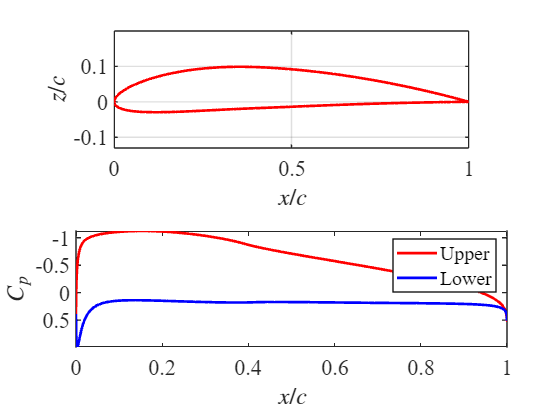

figure;
subplot(2,1,1),plot(x,z,'-r','LineWidth',2)
axis equal
grid;
xlabel('$x/c$','Interpreter','latex')
ylabel('$z/c$','Interpreter','latex')
subplot(2,1,2),plot(xu,Cpu,'-r',xl,Cpl,'-b','LineWidth',2)
hold on
legend('Upper','Lower')
xlabel('$x/c$','Interpreter','latex')
ylabel('$C_p$','Interpreter','latex')
set(gca,'YDir','reverse');

## Calculate lift and moment coefficients.

With the pressure coefficient distribution in hand, we can calculate both lift and moment distributions. To do this, we make use of Simpson's rule for numerical integration, which should be more refined than the trapezoid rule. 

Cl=simps(fliplr(xl),fliplr(Cpl))-simps(xu,Cpu);
CmLE=simps(xu,Cpu.*xu)-simps(fliplr(xl),fliplr(Cpl.*xl));
xCp=-CmLE/Cl;
CmcBy4=Cl/4+CmLE; % for a THIN airfoil x_ac=c/4 by thin airfoil theory

## Core Functions.

Below are the functions required for the script above. These functions are used to generate the coordinates, panels, implement the panel method, and integrate via Simpson's rule.

### Function to create the airfoil coordinates.

This function creates the airfoil coordinates by parsing the NACA 4-digit designation and creating camber and thickness distributions. 

function [x,z,x_u,x_l,z_u,z_l]=NACA4(af_no,no_pls)

% Preallocate arrays.
x_c=linspace(0,pi,floor(no_pls/2));
x_c=(1-cos(x_c))./2;
z_c=linspace(0,pi,floor(no_pls/2));

% Extract airfoil data from NACA airfoil designation.
t=(af_no-floor(af_no/100)*100)/100; % maximum thickness in tenth's of chord
m=floor(af_no/1000)/100; %maximum thickness in tenth's of chord
p=(floor(af_no/100)-floor(af_no/1000)*10)/10; %position of maximum thickness in tenth's of chord

% Create airfoil thickness distribution.
zthick=(t/0.2).*(.2969.*sqrt(x_c)-.126.*x_c-.35160.*x_c.^2+...
    .2843.*x_c.^3-.1036.*x_c.^4);

% Create airfoil camberline. 
for i=1:1:length(x_c)
    if x_c(i)<=p
        z_c(i)=m*(1/p)^2.*(2.*p.*x_c(i)-x_c(i).^2);
    else
        z_c(i)=m*(1/(p-1))^2.*((1-2*p)+2.*p.*x_c(i)-x_c(i).^2);
    end
end

% Create airfoil upper (suction side) and lower (pressure side) surfaces by
% adding thickness distribution to camberline.
z_u=zthick+z_c;
z_l=z_c-zthick;

% Re-arrange coordinates to enable easy plotting. 
z_l=fliplr(z_l(2:end));
x_l=fliplr(x_c(2:end));

z_u=z_u(1:end-1);
x_u=x_c(1:end-1);

if m==0
    z_u(1)=0;
end

z=[z_l z_u]';
x=[x_l x_u]';

end

### Function to create the panels.

function [sth,cth,len]=setUpPanel1(x,z)

N=length(x);

len=zeros(1,N);
sth=len;
cth=len;

for i=1:1:N
    if i==length(x)
        mm=1;
    else
        mm=i+1;
    end
    len(i)=sqrt((x(mm)-x(i))^2+(z(mm)-z(i))^2);
    sth(i)=(z(mm)-z(i))/len(i);
    cth(i)=(x(mm)-x(i))/len(i);
end

end

### Function to calculate influence coefficients.

This function calls calRBeta, which works out the location of each vortex respect to a control point. 


function [coeffs,beta,r]=calCoeffs1(x,z,...
    sth,cth,alpha,V_inf)

A=zeros(length(x)+1,length(x)+1);
b=zeros(1,length(x)+1);

[r,beta]=calRBeta(x,z);

alpha=alpha/180*pi;

for i=1:1:length(x)
    sum=0;
    for j=1:1:length(x)
        if j==length(x)
            mm=1;
        else
            mm=j+1;
        end
        
        sd=sinDiff(sth,cth,i,j);
        cd=cosDiff(sth,cth,i,j);
        
        A(i,j)=sd*log(r(i,mm)/r(i,j))+cd*beta(i,j);
        sum=sum+cd*log(r(i,mm)/r(i,j))-sd*beta(i,j);
        
        
        A(i,j)=A(i,j)/(2*pi);
    end
    A(i,length(x)+1)=sum/(2*pi);
    
    s1=(cos(alpha)*sth(i)-sin(alpha)*cth(i));
    b(i)=V_inf*s1;
end

tt=[1 length(x)];

for j=1:1:length(x)
    if j==length(x)
        mm=1;
    else
        mm=j+1;
    end
    sum=0;
    for k=1:1:length(tt)
        sd=sinDiff(sth,cth,tt(k),j);
        cd=cosDiff(sth,cth,tt(k),j);
        
        sum=sum+(sd*beta(tt(k),j)-...
            cd*log(r(tt(k),mm)/r(tt(k),j)));
    end
    A(length(x)+1,j)=sum/(2*pi);
end


sum2=0;
for k=1:1:length(tt)
    sum1=0;
    for j=1:1:length(x)
        if j==length(x)
            mm=1;
        else
            mm=j+1;
        end
        sd=sinDiff(sth,cth,tt(k),j);
        cd=cosDiff(sth,cth,tt(k),j);
        
        sum1=sum1+(sd*log(r(tt(k),mm)/r(tt(k),j))+...
            cd*beta(tt(k),j));
    end
    sum2=sum2+sum1;
end

A(length(x)+1,length(x)+1)=sum2/(2*pi);
c1=(sin(alpha)*sth(1)+cos(alpha)*cth(1));
c2=(sin(alpha)*sth(length(x))+cos(alpha)*cth(length(x)));
b(length(x)+1)=-V_inf*c1-V_inf*c2;

coeffs=A\b';

end

### Function to calculate relative location of vortices.

r and beta are the radii and angle of each panel control point vs. an origin.

function [r,beta]=calRBeta(x,z)

r=zeros(length(x),length(x));
beta=r;
for i=1:1:length(x)
    if i==length(x)
        xcntr=(x(1)+x(i))/2;
        zcntr=(z(1)+z(i))/2;
    else
        xcntr=(x(i+1)+x(i))/2;
        zcntr=(z(i+1)+z(i))/2;
    end
    
    for j=1:1:length(x)
        r(i,j)=sqrt((xcntr-x(j))^2+(zcntr-z(j))^2);
        
        if i~=j
            if j==length(x)
                k=1;
            else
                k=j+1;
            end
            temp1=(zcntr-z(k))*(xcntr-x(j))-...
                (xcntr-x(k))*(zcntr-z(j));
            temp2=(xcntr-x(k))*(xcntr-x(j))+...
                (zcntr-z(k))*(zcntr-z(j));
            beta(i,j)=atan2(temp1,temp2);
        else
            beta(i,j)=pi;
        end
        
    end
end
end

### Auxiliary Trigonometric Functions.

function [sinD]=sinDiff(sin_theta,cos_theta,i,j)

sinD=(cos_theta(j)*sin_theta(i)-sin_theta(j)*cos_theta(i));

end

function [cosD]=cosDiff(sin_theta,cos_theta,i,j)

cosD=(sin_theta(j)*sin_theta(i)+cos_theta(j)*cos_theta(i));

end

## Function to calculate the tangential velocity distribution on the airfoil.


function [Vt]=calVt(sth,cth,r,beta,V_inf,alpha,coeffs)


q=coeffs(1:end-1);
gamma=coeffs(end);

alpha=alpha/180*pi;

N=size(beta,1);
Vt=zeros(1,N);
for i=1:1:N
    sum1=0;
    sum2=0;
    for j=1:1:N
        if j==N
            mm=1;
        else
            mm=j+1;
        end
        
        sd=sinDiff(sth,cth,i,j);
        cd=cosDiff(sth,cth,i,j);
        
        sum1=sum1+q(j)/(2*pi)*(sd*beta(i,j)-cd*log(r(i,mm)/r(i,j)));
        sum2=sum2+gamma/(2*pi)*(sd*log(r(i,mm)/r(i,j))+cd*beta(i,j));
    end
    c1=sin(alpha)*sth(i)+cos(alpha)*cth(i);
    Vt(i)=V_inf*c1+sum1+sum2;
end

end


## Function to integrate via Simpson's rule.


function z = simps(x,y,dim)
% got this from the mathworks website. credits below

%SIMPS  Simpson's numerical integration.
%   The Simpson's rule for integration uses parabolic arcs instead of the
%   straight lines used in the trapezoidal rule.
%
%   Z = SIMPS(Y) computes an approximation of the integral of Y via the
%   Simpson's method (with unit spacing). To compute the integral for
%   spacing different from one, multiply Z by the spacing increment.
%
%   For vectors, SIMPS(Y) is the integral of Y. For matrices, SIMPS(Y) is a
%   row vector with the integral over each column. For N-D arrays, SIMPS(Y)
%   works across the first non-singleton dimension.
%
%   Z = SIMPS(X,Y) computes the integral of Y with respect to X using the
%   Simpson's rule. X and Y must be vectors of the same length, or X must
%   be a column vector and Y an array whose first non-singleton dimension
%   is length(X). SIMPS operates along this dimension.
%
%   Z = SIMPS(X,Y,DIM) or SIMPS(Y,DIM) integrates across dimension DIM of
%   Y. The length of X must be the same as size(Y,DIM).
%
%   Examples:
%   --------
%   % The integration of sin(x) on [0,pi] is 2
%   % Let us compare TRAPZ and SIMPS
%   x = linspace(0,pi,6);
%   y = sin(x);
%   trapz(x,y) % returns 1.9338
%   simps(x,y) % returns 2.0071
%
%   If Y = [0 1 2
%           3 4 5
%           6 7 8]
%   then simps(Y,1) is [6 8 10] and simps(Y,2) is [2; 8; 14]
%
%   -- Damien Garcia -- 08/2007, revised 11/2009
%   website: <a
%   href="matlab:web('http://www.biomecardio.com')">www.BiomeCardio.com</a>
%
%   See also CUMSIMPS, TRAPZ, QUAD.

%   Adapted from TRAPZ

%--   Make sure x and y are column vectors, or y is a matrix.
perm = []; nshifts = 0;
if nargin == 3 % simps(x,y,dim)
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
elseif nargin==2 && isscalar(y) % simps(y,dim)
  dim = y; y = x;
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
  x = 1:m;
else % simps(y) or simps(x,y)
  if nargin < 2, y = x; end
  [yp,nshifts] = shiftdim(y);
  [m,n] = size(yp);
  if nargin < 2, x = 1:m; end
end
x = x(:);
if length(x) ~= m
  if isempty(perm) % dim argument not given
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the first non-singleton dimension of Y.');
  else
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the DIM''th dimension of Y.');
  end
end

%-- The output size for [] is a special case when DIM is not given.
if isempty(perm) && isequal(y,[])
  z = zeros(1,class(y));
  return
end

%-- Use TRAPZ if m<3
if m<3
    if exist('dim','var')
        z = trapz(x,y,dim);
    else
        z = trapz(x,y);
    end
    return
end

%-- Simpson's rule
y = yp;
clear yp

dx = repmat(diff(x,1,1),1,n);
dx1 = dx(1:end-1,:);
dx2 = dx(2:end,:);

alpha = (dx1+dx2)./dx1/6;
a0 = alpha.*(2*dx1-dx2);
a1 = alpha.*(dx1+dx2).^2./dx2;
a2 = alpha.*dx1./dx2.*(2*dx2-dx1);

z = sum(a0(1:2:end,:).*y(1:2:m-2,:) +...
    a1(1:2:end,:).*y(2:2:m-1,:) +...
    a2(1:2:end,:).*y(3:2:m,:),1);

if rem(m,2) == 0 % Adjusting if length(x) is even   
    state0 = warning('query','MATLAB:nearlySingularMatrix');
    state0 = state0.state;
    warning('off','MATLAB:nearlySingularMatrix')
    C = vander(x(end-2:end))\y(end-2:end,:);
    z = z + C(1,:).*(x(end,:).^3-x(end-1,:).^3)/3 +...
        C(2,:).*(x(end,:).^2-x(end-1,:).^2)/2 +...
        C(3,:).*dx(end,:);
    warning(state0,'MATLAB:nearlySingularMatrix')
end

%-- Resizing
siz = size(y); siz(1) = 1;
z = reshape(z,[ones(1,nshifts),siz]);
if ~isempty(perm), z = ipermute(z,perm); end

end